% Chose your material
Material = "Silicon P-N"

Material = "Silicon P-N"

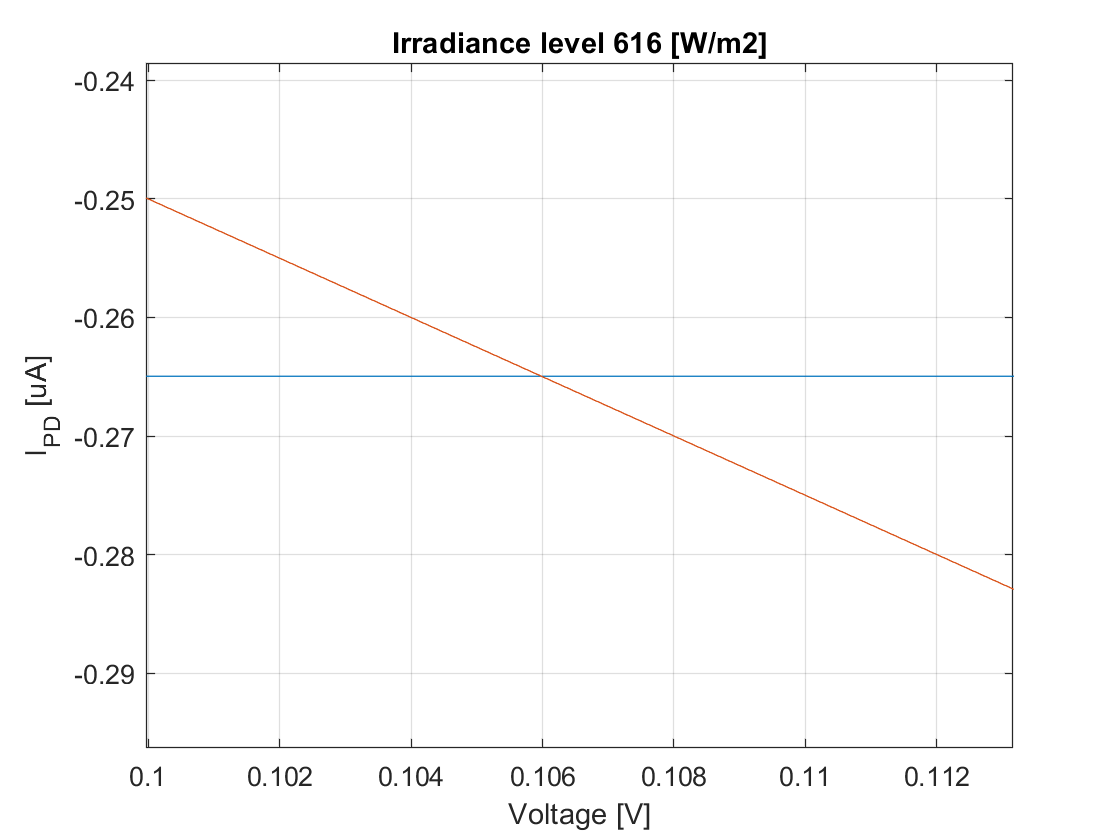


% Pulse duration
t = 4*10^(-3); % [s]

% Irradiance limit
I_lim = 22*10^(3); %[W/m2]

% Light intensity
P_light_in = I_lim *0.14; % [W/m2] <--- if 10^(6) good but I have 10^(3)
P = 0.2 * P_light_in;
% Photodiode surface (variable side length in [um])
l = 10^(-6)*155; % [m] triangle side length
a = 10^(-6)*40; % [m] active electrode radius
S = sqrt(3)/4*l^2 - pi*a^2; % [m2]

% Light to current conversion
alpha = 0.08; % [A/W]

if Material=="Silicon P-N"
    % Dark saturation current
    I0 = 1.5e-06; % [A/m2]
    % Diode ideality factor
    n = 1.0; % For one diode in "series"
elseif Material=="Polymer"
    % Dark saturation current
    I0 = 4.5*10^(-5); % [A/m2]
    % Diode ideality factor
    n = 1.2; % For one diode in "series"
end

% V0 = kT/q
k = 1.38064852*10^(-4); % [m2*kg/s2/K]
T = 310.15; % [K] ~37°C
q = 1.60217662; % [C]
V0 = k*T/q;

% Shunt resistance resistance
%Rsh = 15*10^(3); % [Ohnm] <-------------------------------------- TO VERIFY
% Photodiode surface

% Load resistance
R_L = 400000; % [Ohm]

% I-V curve
I_PD = @(V) 10^6*(-alpha*P*S+I0*S*(exp(V/(n*V0))-1));
fplot(I_PD, [-0.5 0.6]);
hold on;
fplot(@(V) -10^6*V/R_L, [0,0.6]);
hold off;
grid on;
title("Irradiance level "+P+" [W/m2]");
xlabel('Voltage [V]');
ylabel('I_P_D [uA]');
ylim([-1 0.1]);


% Find intersection
% x=linspace(-0.5,0.9, 10000);
% I_PDx = 10^6*(-alpha*P*S+I0*S*(exp(x/(n*V0))-1));
% I_Rx = -x/R_L;
% Intersections=find(abs(I_Rx-I_PDx)<=(0.001));
% % Get intersection values
% V_int=x(Intersections);
% V_int = mean(V_int);
% I_int = 10^(6)*mean(-V_int./R_L);
% Int_val = sprintf("Intersection \n - Current: %f [uA] \n - Voltage: %f [V]",I_int,V_int);
% disp(Int_val);
% 
% % Current density of material given by I-V curve for given R_L
% J = 0;
